# Homework 2

## Natalie Shen

clear all;
close all;
clc;

### 1)

The rolling sevens is more probability as there are more ways to get sevens than snake eyes. Snake eyes only happens on one instance, both die turn up 1. For sevens, there are three ways of getting seven, 1-6, 2-5 and 3-4. We can inverse them too as it doesn't matter which die gives the number per set, so we can include 6-1, 5-2 and 4-3, making for a total of six ways to get sevens. Since there are 36 possible combinations between two die (6 * 6 = 36), then the ratio for snake eyes is 1:36 and the ratio for sevens is 6:36 or 1:6.

### 2)

Sums:

2     

- 1+1

1/36

3

- 1+2

- 2+1

2/36 or 1/18

4

- 1+3

- 3+1

- 2+2

3/36 or 1/12

5

- 1+4

- 4+1

- 2+3

- 3+2

4/36 or 1/9

6

- 1+5

- 5+1

- 2+4

- 4+2

- 3+3

5/36

7

- 1+6

- 6+1

- 2+5

- 5+2

- 3+4

- 4+3

6/36 or 1/6

8

- 2+6

- 6+2

- 3+5

- 5+3

- 4+4

5/36

9

- 3+6

- 6+3

- 4+5

- 5+4

4/36 or 1/9

10

- 4+6

- 6+4

- 5+5

3/36 or 12

11

- 5+6

- 6+5

2/36 or 1/18

12

- 6+6

1/36

p = 6*6;
x = zeros(1,p);
count = 0;

for dice1 = 1:1:6
    sum = dice1;
    for dice2 = 1:1:6
        count = count + 1;
        sum = sum + dice2;
        x(count) = sum;
        sum = dice1;
    end
end
disp(x)

  Columns 1 through 23

     2     3     4     5     6     7     3     4     5     6     7     8     4     5     6     7     8     9     5     6     7     8     9

  Columns 24 through 36

    10     6     7     8     9    10    11     7     8     9    10    11    12



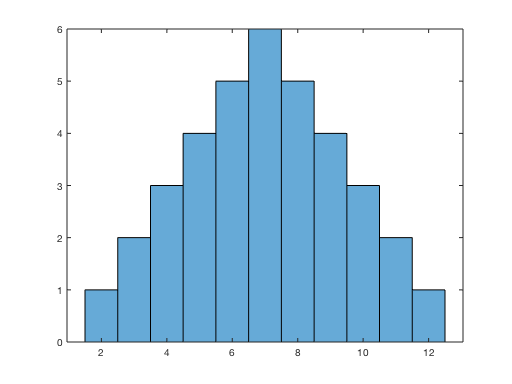

histogram(x)


[N,edges] = histcounts(x);
y = zeros(1,length(N));
s = [2 3 4 5 6 7 8 9 10 11 12];
disp("Probabilities of (in percentages)")

Probabilities of (in percentages)


for r = 1:1:length(N)
    disp(s(r))
    per = (N(r) / p) * 100
    y(N) = per;
end

     2



per = 2.7778

     3



per = 5.5556

     4



per = 8.3333

     5



per = 11.1111

     6



per = 13.8889

     7



per = 16.6667

     8



per = 13.8889

     9



per = 11.1111

    10



per = 8.3333

    11



per = 5.5556

    12



per = 2.7778

### 3)

%mean and variance of the sums
mean(x)

ans = 7

V = var(x)

V = 6

%mean and variance of the probabilities
mean(y)

ans = 1.5152

V = var(y)

V = 2.1044

### 4)

p = 6^10;
x = zeros(1,p);
count = 0;
record = 0;

for dice1 = 1:1:6
    sum = dice1;
    record = sum;
    for dice2 = 1:1:6
        sum = sum + dice2;
        
        for dice3 = 1:1:6
            sum 
        end
        sum = record;
    end
end
disp(x)
histogram(x)